# Rainbow Road

## Exercise 6.1:

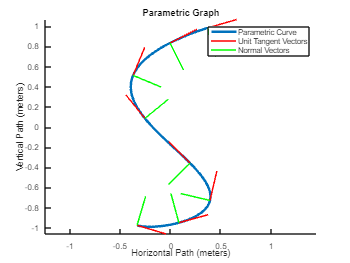

%DEFINING VARIABLES AND PLOTING ORIGINAL GRAPH
syms t;
u = t*.1; % 0 - 32 seconds (u is function of t)
x=0.3960*cos(2.65*(u+1.4));
y=-0.99*sin(u+1.4);


t_vals = linspace(0,32,200);

x_vals=double(subs(x,t_vals));
y_vals=double(subs(y,t_vals));

clf;
figure;
hold on;
plot(x_vals, y_vals, 'LineWidth',3);
xlabel('Horizontal Path (meters)');
ylabel('Vertical Path (meters)');
title('Parametric Graph')
axis equal;

%TANGENT FUNCTION 
velocity_x=diff(x);
velocity_y=diff(y);
speed = sqrt(velocity_x^2+velocity_y^2);
tangent_x = velocity_x/speed; 
tangent_y = velocity_y/speed;

%NORMAL FUNCTION 
qx = diff(tangent_x);
qy = diff(tangent_y);
q_norm = sqrt(qx^2+qy^2);

normal_x = qx/q_norm; 
normal_y = qy/q_norm;

%PLOTING IN TANGENT AND NORMAL LINES INTO GRAPH
length_1=0.3;
change_t=linspace(0,32,8);
for t_vals=change_t
    x_plot=double(subs(x,t_vals));
    y_plot=double(subs(y, t_vals));
    tangent_x_plot=double(subs(tangent_x, t_vals));
    tangent_y_plot=double(subs(tangent_y, t_vals));

    A=[x_plot,x_plot+tangent_x_plot*length_1];
    B=[y_plot, y_plot+tangent_y_plot*length_1];
    plot(A, B, 'r', 'LineWidth',1);
end

for t_vals=change_t
    x_plot=double(subs(x,t_vals));
    y_plot=double(subs(y, t_vals));
    normal_x_plot=double(subs(normal_x, t_vals));
    normal_y_plot=double(subs(normal_y, t_vals));

    A=[x_plot,x_plot+normal_x_plot*length_1];
    B=[y_plot, y_plot+normal_y_plot*length_1];
    plot(A, B, 'g', 'LineWidth',1);
end

legend('Parametric Curve','Unit Tangent Vectors', '', '', '', '', '', '', '', 'Normal Vectors');
hold off;

## Exercise 6.2:

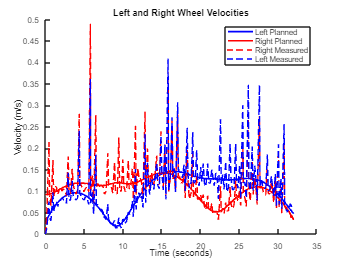

%DEFINING PARAMETERS
d = 0.245;
t_vals = linspace(0,32,200);
theta_dot =tangent_x*qy-tangent_y*qx;
velocity_left=speed-0.5*d*theta_dot;
velocity_right=speed+0.5*d*theta_dot;


%EVAULATING FUNCTIONS
velocity_left_vals=double(subs(velocity_left,t, t_vals));
velocity_right_vals=double(subs(velocity_right,t, t_vals));


%PLOTING FUNCTION
clf;
hold on;
plot(t_vals,velocity_left_vals,'b','LineWidth',2);
plot(t_vals, velocity_right_vals, 'r', 'LineWidth',2);
plot(tlist_measured(1:end-1), right_wheel_velocity, 'r--');
plot(tlist_measured(1:end-1), left_wheel_velocity, 'b--');
title('Left and Right Wheel Velocities');
legend('Left Planned', 'Right Planned', 'Right Measured', 'Left Measured');
xlabel('Time (seconds)')
ylabel('Velocity (m/s)')
hold off;

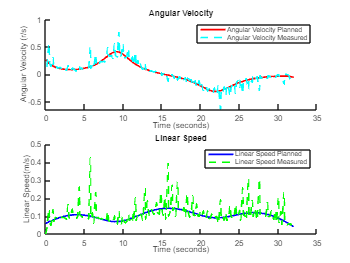

speed_measured = sqrt(vx.^2+vy.^2);
tangent_x_measured = vx./speed_measured; 
tangent_y_measured = vy./speed_measured;
qx_measured = diff(tangent_x_measured) ./ diff(tlist_measured(1:end-1));
qy_measured = diff(tangent_y_measured)./ diff(tlist_measured(1:end-1));
theta_dot_measured =tangent_x_measured(1:end-1).*qy_measured-tangent_y_measured(1:end-1).*qx_measured;
angular_velocity_measured = theta_dot_measured;


angular_velocity = double(subs(theta_dot,t, t_vals));
speedvals = double(subs(speed,t, t_vals));
subplot(2,1,1);
hold on;
plot(t_vals, angular_velocity, 'r', 'LineWidth',2);
plot(tlist_measured(1:end-2), angular_velocity_measured, 'c--', 'LineWidth',2);
hold off;
title('Angular Velocity');
xlabel('Time (seconds)');
ylabel('Angular Velocity (r/s)');
legend('Angular Velocity Planned', 'Angular Velocity Measured');
subplot(2,1,2);
hold on;
plot(t_vals, speedvals,'b', 'LineWidth',2);
plot(tlist_measured(1:end-1), speed_measured, 'g--', 'Linewidth', 2);
hold off;
title('Linear Speed');
xlabel('Time (seconds)');
ylabel('Linear Speed(m/s)');
legend('Linear Speed Planned', 'Linear Speed Measured');
hold off

## Exercise 6.2

% %connect to the neato at IP address 192.168.16.01
neatov3.connect('192.168.16.91');
%define a list of time values from 0 to 70 (seconds)
%to evaluate vl(t) and vr(t) beforehand
% t_range = 0:.2:32;
% %evaluate vl(t) and vr(t) for t = t_range
% %result should be two lists
% vl_range = double(subs(velocity_left,t_range));
% vr_range = double(subs(velocity_right,t_range));

%initialize recorded data
recorded_data = []

tic;
iter = 1;
while toc<=32
    t_in = toc;   
    vl_out = interp1(t_vals,velocity_left_vals,t_in);
    vr_out = interp1(t_vals,velocity_right_vals,t_in);
    neatov3.setVelocities(vl_out, vr_out);
    sensors = neatov3.receive();
    if length(sensors.encoders)>=2
        xl = sensors.encoders(1);
        xr = sensors.encoders(2);
        recorded_data(iter,:)=[t_in,xl,xr,vl_out,vr_out];
        iter = iter + 1;
    end

end

neatov3.setVelocities(0,0);

sensors = neatov3.receive();

neatov3.disconnect();

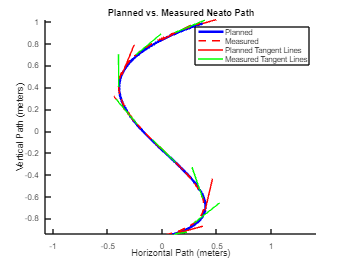

recorded_data = recorded_data(1:177, :);
tlist_measured = recorded_data(:,1);
left_wheel_velocity = diff(recorded_data(:, 2))./diff(recorded_data(:,1));
right_wheel_velocity = diff(recorded_data(:, 3))./diff(recorded_data(:,1));

omega = (right_wheel_velocity - left_wheel_velocity)/d;
theta = -pi/10+[0;cumsum(omega.*diff(recorded_data(:,1)))];
signed_speed_approx = (left_wheel_velocity+ right_wheel_velocity)/2;

vx_approx = cos(theta(1:end-1)).*signed_speed_approx;
vy_approx = sin(theta(1:end-1)).*signed_speed_approx;


px_approx = [0;cumsum(vx_approx.*diff(recorded_data(:,1)))];
py_approx = [0;cumsum(vy_approx.*diff(recorded_data(:,1)))];

vx= diff(px_approx)./ diff(recorded_data(:,1));
vy= diff(py_approx)./ diff(recorded_data(:,1));

clf;
hold on;
plot(x_vals, y_vals,'b', 'LineWidth',3);
plot(px_approx - 0.36, py_approx - 0.96, 'r--', 'LineWidth',2)
title('Planned vs. Measured Neato Path');
length_1=0.3;
change_t=linspace(0,32,8);
for t_vals=change_t
    x_plot=double(subs(x,t_vals));
    y_plot=double(subs(y, t_vals));
    tangent_x_plot=double(subs(tangent_x, t_vals));
    tangent_y_plot=double(subs(tangent_y, t_vals));

    A=[x_plot,x_plot+tangent_x_plot*length_1];
    B=[y_plot, y_plot+tangent_y_plot*length_1];
    plot(A, B, 'r', 'LineWidth',1);
end
for i = 1:20:177
    px_approx(i) = px_approx(i) - 0.36;
    py_approx(i) = py_approx(i) - 0.96;
    x_plot_measured= px_approx(i) + tangent_x_measured(i)*length_1;
    y_plot_measured= py_approx(i) + tangent_y_measured(i)*length_1;

    line([px_approx(i), x_plot_measured], [py_approx(i), y_plot_measured], color='g');
end
hold off;
axis equal;
xlabel('Horizontal Path (meters)');
ylabel('Vertical Path (meters)');
legend('Planned', 'Measured', 'Planned Tangent Lines', '' , '', '', '', '', '', '', 'Measured Tangent Lines');